load('R.mat')
ss=3; %%how much you want to subsample by- this will affect performance so be consistant, 3 is ~ 100 ms bins,also try 500 (from Anderson paper)
makeEvsMatrix_ss

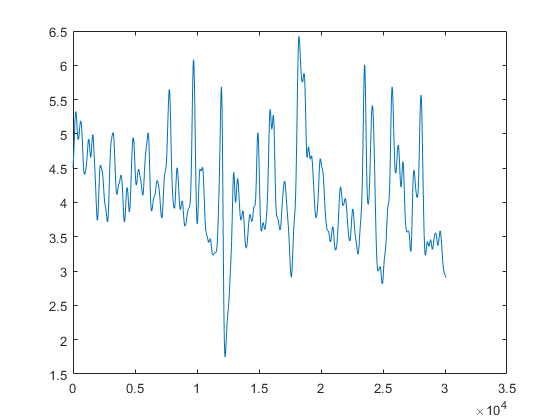

filterWidth=100;
plot(filterGauss(sum(evs_matrix_ss),filterWidth))

Make Labels

load('R')
timeStamps=cell2mat(R.TimeStamps)';
pos_ss=R.Pos.t(1:ss:end);

    for r=1:length(timeStamps)
        q= pos_ss;
        val(r) = timeStamps(r); %value to find
        
    end
    
    closest_ind=ones(1,length(timeStamps));
    for aa=1:length(timeStamps)
        tmp = abs(q-val(aa));
        [idx idx]= min(tmp); %index of closest value
        closest_ind(aa)=idx;
    end
    
numSess=input('how many sessions?');
Start=ones(1,5);End=ones(1,5);
for aa=1:numSess
    Start(aa)=closest_ind(2*aa-1);
    End(aa)=closest_ind(2*aa);
end

Labels=zeros(1,length(pos_ss));
    for aa=1:numSess
        Labels(Start(aa):End(aa))=aa;
    end
    
    clearvars -except Labels evs_matrix_ss ss

Velocity Filter

%     load('R.mat')
%     vel=speed2D(R.Pos.x1(1:ss:end),R.Pos.y1(1:ss:end),R.Pos.t(1:ss:end));
%     vel_ss=vel(1:end);
%     speedFiltinds=find(vel_ss>3);
%     
%     evs_matrix_filt=evs_matrix_ss(:,speedFiltinds);
%     Labels=Labels(:,speedFiltinds);

%    rng default
%    Mdl=fitcecoc(evs_matrix_filt',Labels')

Decode Session using Multiclass SVM

   rng default
   Mdl=fitcecoc(evs_matrix_ss',Labels')

%    %%,'OptimizeHyperparameters','auto',...
%     'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
%     'expected-improvement-plus'))
CVSVMModel = crossval(Mdl);
classLoss = kfoldLoss(CVSVMModel)
isLoss=resubLoss(Mdl)

[Mdl_labels,scores]=predict(Mdl,evs_matrix_ss')
PredictCorrect=find(Mdl_labels==Labels');
percentCorrect=length(PredictCorrect)/length(Labels)

Shuffle Data

evs_matrix=evs_matrix_ss;
evs_matrix_sh=evs_matrix(:,randperm(size(evs_matrix,2)));
filterWidth=100;
plot(filterGauss(sum(evs_matrix),filterWidth));hold on;filterWidth=100;
plot(filterGauss(sum(evs_matrix_sh),filterWidth));hold off

[chance_labels,scores]=predict(Mdl,evs_matrix_sh')

PredictCorrect_sh=find(chance_labels==Labels');
percentCorrect_sh=length(PredictCorrect_sh)/length(Labels)

Winner Take All

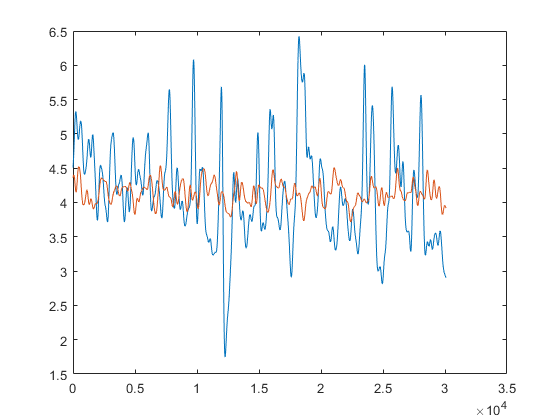

hab_sh=mode(chance_labels(Labels==1))

cups_sh=mode(chance_labels(Labels==2))
fam1_sh=mode(chance_labels(Labels==3))
novel_sh=mode(chance_labels(Labels==4))
%fam2_sh=mode(chance_labels(Labels==5))

hab=mode(Mdl_labels(Labels==1))
cups=mode(Mdl_labels(Labels==2))
fam1=mode(Mdl_labels(Labels==3))
novel=mode(Mdl_labels(Labels==4))
%fam2=mode(Mdl_labels(Labels==5))

Visualize where Decoding is performing well

load('R.mat')
x1=R.Pos.x1(1:ss:end);
y1=R.Pos.y1(1:ss:end);
t=R.Pos.t(1:ss:end);
plot(x1,y1)

theseLabels=find(Labels==4);
theseMLabels=find(Mdl_labels==4);
correct_inds=ismember(theseMLabels',theseLabels);
correct= theseMLabels(correct_inds);
plot(x1(Labels==4),y1(Labels==4),'k')
hold on
plot(x1(correct),y1(correct),'.r')
hold off
axis off

set(gcf,'color',[1 1 1]);
axis square
drawnow;
        
[map,pospdf] = ratemap(x1(correct),y1(correct),x1(Labels==4),y1(Labels==4),R.Pos.t(Labels==4),R.p.smoothing,R.mapAxis,R.mapAxis);
map(R.visited==0) = NaN;
drawfield(map,R.mapAxis,'jet',max(max(map)),R.p.binWidth,R.p.smoothing); %colorbar
axis off

%%one vs one sessions decodingcl
numChunks=5;%% numChunks is crossval
for i=1:max(Labels)
    
    for j=1:max(Labels)
        [CorrectTrain{i,j},CorrectTest{i,j}]=DecodeInteraction(evs_matrix_ss(:,Labels==i),evs_matrix_ss(:,Labels==j),Labels(:,Labels==i),Labels(:,Labels==j),numChunks,0);
    end
end

clear memory
%%one vs one sessions decoding
numChunks=5;%% numChunks is crossval
for i=1:max(Labels)
    for j=1:max(Labels)
        [~,CorrectTest_sh{i,j}]=DecodeInteraction(evs_matrix_sh(:,Labels==i),evs_matrix_ss(:,Labels==j),Labels(:,Labels==i),Labels(:,Labels==j),numChunks,0);
    end
end
CT=cell2mat(CorrectTest);CT(CT==0)=NaN;
CT_sh=cell2mat(CorrectTest_sh);CT_sh(CT_sh==0)=NaN;
CTmeans=zeros(max(Labels));
for i=1:max(Labels)
    for j=1:max(Labels)
    thisSess=CorrectTest{i,j}(:,:);thisSess(thisSess==0)=NaN;   

    CTmeans(i,j)=mean(nanmean(thisSess));
    CTstd(i,j)=mean(nanstd(thisSess));
    end
end


CTmeans(CTmeans==1)=0;
heatmap(CTmeans,'CellLabelColor','none');
        colormap('viridis'); caxis([.5 1])
    
    
CT_sh=cell2mat(CorrectTest_sh);CT_sh(CT_sh==0)=NaN;
CTmeans_sh=zeros(max(Labels));

for i=1:max(Labels)
    for j=1:max(Labels)
    thisSess=CorrectTest_sh{i,j}(:,:);thisSess(thisSess==0)=NaN;   
    CTmeans_sh(i,j)=mean(nanmean(thisSess));
    
    CTstd_sh(i,j)=mean(nanstd(thisSess));
    end
end
CTmeans_sh(CTmeans_sh==1)=0;
heatmap(CTmeans_sh,'CellLabelColor','none');colormap('viridis'); caxis([.5 1])

for ii=1:length(CT)
    test(:,ii)=reshape(CT{ii},[],1);
end

test(test==1)=NaN;

for ii=1:length(CT)
    test_sh(:,ii)=reshape(CT_sh{ii}{2,1},[],1);
end

test_sh(test_sh==0)=NaN;

for i=1:numChunks
    for j=1:unique(Labels)
    thisSess=CorrectTest{i,j}(:,:);thisSess=reshape(thisSess,[],1);thisSess(thisSess==0)=NaN;
    thisSess_sh=CorrectTest_sh{i,j}(:,:);thisSess_sh=reshape(thisSess_sh,[],1);thisSess_sh(thisSess==0)=NaN;
    
    p(i,j)=ranksum(thisSess,thisSess_sh);
    
    end
end
disp(p)
save('context_stats','p')

animalIDs=ls('*3c*');
sessions={'hab', 'cups', 'fam1', 'nov','fam2'};yy=size(animalIDs);

    for hh=1:yy(1)-3
        cd(animalIDs(hh,1:end))
        load('ContextDecode.mat')
        CT(CT==1)=NaN;
        CT_sh(CT_sh==1)=NaN;
        
        test=reshape(CT,[],1);
        shuf=reshape(CT_sh,[],1);

        p(hh)=ranksum(test(~isnan(test)),shuf(~isnan(shuf)));
        
        thisCT(:,hh)=test;
        this_shuf(:,hh)=shuf;
        
        clearvars CT CT_sh
        cd ..
    end
    


CT_average=CTmeans-CTmeans_sh;
heatmap(CT_average);colormap('viridis')

%%now interaction zones- do 1 by 1 for all sessions

Interaction Zones


load('R.mat');load('cups.mat')

posdata={R.Pos.x1 R.Pos.y1};
rad=12;
hk=[cups.lxc cups.lyc];
[~,Int_indsL] = pointsincircle(posdata,rad,hk);    


%load('evs_matrix.mat')

evsmatrixLInt=evs_matrix_ss(:,Int_indsL);
evsmatrixLInt_sh=evs_matrix_sh(:,Int_indsL);
LabelsL=Labels(:,Int_indsL);

[Mdl_labels,scores]=predict(Mdl,evsmatrixLInt')


Stats

for i=1:numChunks
    for j=1:numChunks
    thisSess=CorrectTest{i,j}(:,:);thisSess=reshape(thisSess,[],1);
    thisSess_sh=CorrectTest_sh{i,j}(:,:);thisSess_sh=reshape(thisSess_sh,[],1);
    
    p(i,j)=ranksum(thisSess,thisSess_sh);
    
    end
end
save('stats_Lint','p')
disp(p)

tic
numChunks=5;%% numChunks is crossval
for i=1:max(Labels)
    for j=1:max(Labels)
        [CorrectTrain{i,j},CorrectTest{i,j},Mdl{i,j}]=DecodeInteraction(evsmatrixRInt(:,LabelsR==i),evsmatrixRInt(:,LabelsR==j),LabelsR(:,LabelsR==i),LabelsR(:,LabelsR==j),numChunks,0);
    end
end
toc

CT=cell2mat(CorrectTest);CT(CT==0)=NaN;
CTmeans=zeros(numChunks);
for i=1:numChunks
    for j=1:numChunks
    thisSess=CorrectTest{i,j}(:,:);thisSess(thisSess==0)=NaN;   
    CTmeansR(i,j)=mean(nanmean(thisSess));
    CTstd(i,j)=mean(nanstd(thisSess));
    end
end
heatmap(CTmeansR);colormap('default')

evs_matrix=evsmatrixRInt;
evs_matrix_sh=evs_matrix(:,randperm(size(evs_matrix,2)));
filterWidth=100;
plot(filterGauss(sum(evs_matrix),filterWidth));hold on;filterWidth=100;
plot(filterGauss(sum(evs_matrix_sh),filterWidth));hold off

%%one vs one sessions decoding
numChunks=5;%% numChunks is crossval
evs_matrix_sh=evsmatrixLInt_sh;
Labels=Labels;
for i=1:max(Labels)
    parfor j=1:max(Labels)
        [~,CorrectTest_sh{i,j},~]=DecodeInteraction(evs_matrix_sh(:,Labels==i),evs_matrix_sh(:,Labels==j),Labels(:,Labels==i),Labels(:,Labels==j),numChunks,0);
    end
end

CT_sh=cell2mat(CorrectTest_sh);CT_sh(CT_sh==0)=NaN;
CTmeans_shR=zeros(numChunks);
for i=1:numChunks
    for j=1:numChunks
    thisSess=CorrectTest_sh{i,j}(:,:);thisSess(thisSess==0)=NaN;   
    CTmeans_shR(i,j)=mean(nanmean(thisSess));
    CTstd_sh(i,j)=mean(nanstd(thisSess));
    end
end
heatmap(CTmeans_shR);colormap('default')

for i=1:numChunks
    for j=1:numChunks
    thisSess=CorrectTest{i,j}(:,:);thisSess=reshape(thisSess,[],1);
    thisSess_sh=CorrectTest_sh{i,j}(:,:);thisSess_sh=reshape(thisSess_sh,[],1);
    
    p(i,j)=ranksum(thisSess,thisSess_sh);
    
    end
end
save('stats_Lint','p')
disp(p)

Is decoding performance correlated with velocity?

correct_inds=find(Mdl_labels==Labels');
incorrect_inds=find(Mdl_labels~=Labels');
speed = speed2D(x1,y1,t);
speed_correct=speed(correct_inds);
speed_incorrect=speed(incorrect_inds)
boxplot(speed, speed_correct)
%boxplot(speed_correct)
ranksum(speed, speed_correct)

Is there anything different in the LFP?

%%choose a good channel from neuraview
[CSC7_Samples,CSC7_TimeStamps]=straightenCSC(R.CSC.CSC7_Samples,R.CSC.CSC7_TimeStamps);
CSC7_Samples(CSC7_Samples==0)=[];CSC7_TimeStamps=CSC7_TimeStamps(1:length(CSC7_Samples));
plot(CSC7_TimeStamps,CSC7_Samples)

%%how/when to sub
ss_CSC=round(length(CSC7_Samples)/length(t));
CSC_ss=CSC7_Samples(1:ss_CSC:end);CSCT_ss=CSC7_TimeStamps(1:ss_CSC:end);
plot(CSCT_ss,CSC_ss)

timewin=1; %1 for theta
timebandwidth=2;
params.tapers=[timebandwidth timebandwidth*2-1];%alex uses 2 3
params.pad=2;
params.Fs=2000;
params.fpass=[0 100];
params.err=[1 2];
params.trialave=0;


movingwin=[.5 .05];
[spectrogram,T,f]=mtspecgramc(CSC7_Samples,movingwin,params);
log_spectrogram=log(spectrogram);
plot_matrix(spectrogram,T,f);
xlabel([]); % plot spectrogram
 colorbar;
colormap(jet)


%%make labels for CSC vector
pos_ss=R.Pos.t(1:ss:end);

    for r=1:length(CSC7_TimeStamps)
        q= pos_ss;
        val(r) =CSC7_TimeStamps(r)-CSC7_TimeStamps(1); %value to find
        
    end
    
    closest_ind=ones(1,length(CSC7_TimeStamps));
    for aa=1:length(CSC7_TimeStamps)
        tmp = abs(q-val(aa));
        [idx idx]= min(tmp); %index of closest value
        closest_ind(aa)=idx;
    end
    
    Labels_CSC=zeros(length(CSC7_TimeStamps));
    Labels_CSC=Labels(closest_ind);

Mdl_CSC=fitcecoc(CSC7_Samples',Labels_CSC');

%%compute theta power for different time bins
timewin=1; %1 for theta
timebandwidth=2;
params.tapers=[timebandwidth timebandwidth*2-1];%alex uses 2 3
params.pad=2;
params.Fs=2000;
params.fpass=[2 20];
params.err=[1 2];
params.trialave=0;


[S,f,Serr] = mtspectrumc( CSC7_Samples, params );
plot(f,S)

%%index for the right times
ts_correct=t(PredictCorrect);